% Aidan Fitzpatrick ROB-GY 7863 AMR Project 
% 4-Wheeled Anti-Ackermann (RWD) Drive ~ Kinematic Model Validation

% (Fiding the relation between the wheels’ velocities to the local frame (robot’s frame) and the global frame)
 

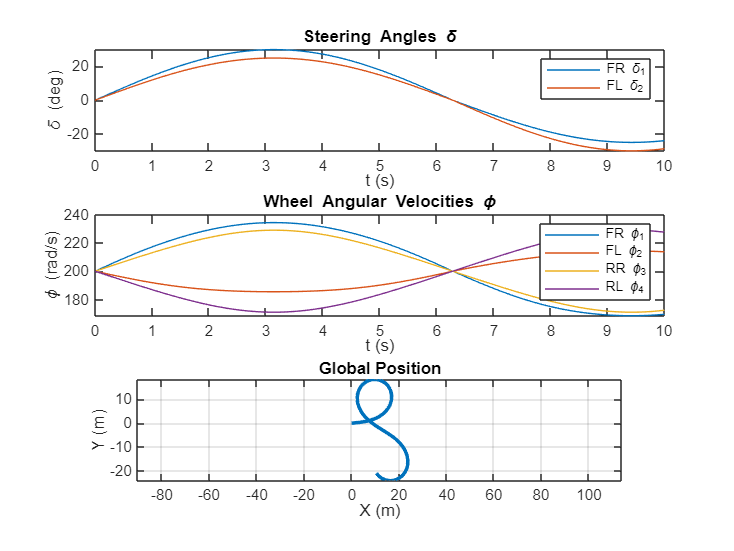

% STATIC Vx************************************************************
 
clc
clear all
close all

% Vehicle geometry (based on real f1 car specifications)
l = 3.6/2; % half wheelbase (m)
b = 2.0/2; % half trackwidth (m)
rw = 0.05; % wheel radius (m)
L = 2*l; % full wheelbase (for use later in calculating omega

% Wheel coordinates consensus (x = forward / y = left) @ COG/COM of car
x = [ +l; +l; -l; -l]; % FR=1 FL=2 RR=3 RL-4
y = [ -b; +b; -b; +b]; % FR=1 FL=2 RR=3 RL-4

% Time
dt = 0.05; % timestep (1/20 s)
t = 0:dt:10; % time vector (10s)

% Vc (STATIC)
Vx = 10.0; % forward velo m/s
Vy = 1.0; % lateral evlo


delta1 = zeros(size(t)); % front right
delta2 = zeros(size(t)); % front left
delta3 = zeros(size(t)); % rear right
delta4 = zeros(size(t)); % rear left




% The 'outermost' wheel > innermost for anti-ackermann, use 1.2x factor

base_angle = deg2rad(25) * sin(0.5 * t); % steering profile = simple sinusoidal pattern

for k = 1:length(t)
    if base_angle(k) >= 0  % left
        delta2(k) = base_angle(k); % left = inside
        delta1(k) = 1.2*base_angle(k); % right = outside
    else  % right
        delta1(k) = base_angle(k); % right = inside
        delta2(k) = 1.2*base_angle(k); % left = outside
    end
end






phi = zeros(4, numel(t)); 
vw  = zeros(4, numel(t)); 
X   = zeros(1, numel(t));
Y   = zeros(1, numel(t));
Theta = zeros(1, numel(t));
X(1) = 0;
Y(1) = 0;
Theta(1) = 0;




for k = 1:numel(t)
    delta = [delta1(k); delta2(k); delta3(k); delta4(k)];

    % Compute yaw rate from steering (Ackermann/Bicycle mode)
    delta_eq = 0.5*(delta1(k) + delta2(k)); % equivalent steering angle = avg
    omega = (Vx/L)*tan(delta_eq);

    Vc = [Vx; Vy; omega];

    % Recalculate Jacobian
    J = zeros(4,3);
    for i = 1:4
        J(i,1) = cos(delta(i));
        J(i,2) = sin(delta(i));
        J(i,3) = -y(i)*cos(delta(i)) + x(i)*sin(delta(i));
    end

    vw(:,k)  = J*Vc;          
    phi(:,k) = (1/rw)*vw(:,k); 


    
    
    if k < numel(t)
        R = [cos(Theta(k)) -sin(Theta(k)) 0;
             sin(Theta(k)) cos(Theta(k)) 0;
             0 0 1];
        Vg = R * Vc; % V_global

        X(k+1) = X(k) + Vg(1)*dt;
        Y(k+1) = Y(k) + Vg(2)*dt;
        Theta(k+1) = Theta(k) + Vg(3)*dt;
    end
end












figure;
subplot(3,1,1);
plot(t, rad2deg([delta1; delta2]));
ylabel('\delta (deg)');
xlabel('t (s)');
title('Steering Angles \delta');
legend('FR \delta_{1}','FL \delta_{2}');

subplot(3,1,2);
plot(t, phi);
ylabel('\phi (rad/s)');
xlabel('t (s)');
legend('FR \phi_{1}','FL \phi_{2}','RR \phi_{3}','RL \phi_{4}');
title('Wheel Angular Velocities \phi');

subplot(3,1,3);
plot(X, Y, 'LineWidth', 2);
xlabel('X (m)');
ylabel('Y (m)');
title('Global Position');
axis equal; grid on;

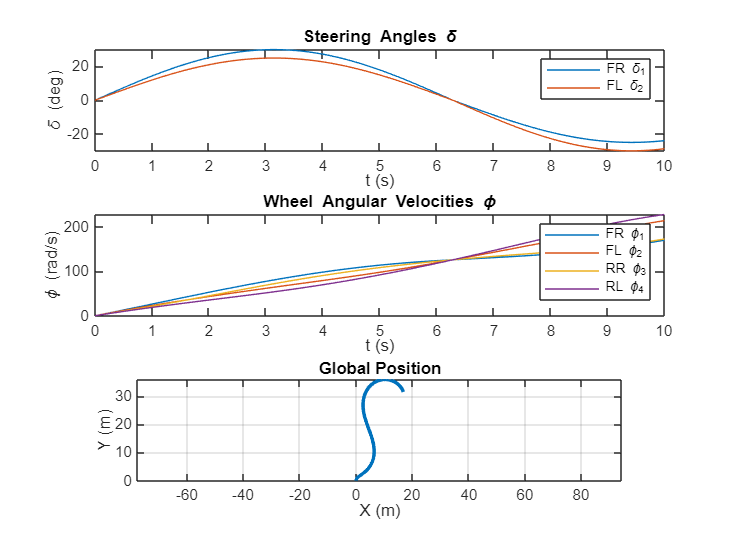

% INCREASING Vx***********************************************************

clc
clear all
close all

% Vehicle geometry (based on real f1 car specifications)
l = 3.6/2; % half wheelbase (m)
b = 2.0/2; % half trackwidth
rw = 0.05; % wheel radius
L = 2*l; % full wheelbase (for use later in calculating omega




x = [ +l; +l; -l; -l ]; % FR=1 FL=2 RR=3 RL-4
y = [ -b; +b; -b; +b ]; % FR=1 FL=2 RR=3 RL-4

dt = 0.05; % timestep (1/20)
t = 0:dt:10; % time vector (10s)




% Vc input now increasing over time
Vx = linspace(0,10,numel(t)); % forward velocity (m/s)
Vy = 1.0; % lateral velocity





delta1 = zeros(size(t)); % front right
delta2 = zeros(size(t));  % front left
delta3 = zeros(size(t)); % rear right fixed
delta4 = zeros(size(t)); % rear left fixed

% The 'outermost' wheel > innermost for anti-ackermann, I use 1.2x factor



base_angle = deg2rad(25) * sin(0.5 * t);% steering simple sinusoidal pattern

for k = 1:length(t)
    if base_angle(k) >= 0  % left
        delta2(k) = base_angle(k); % left = inside
        delta1(k) = 1.2*base_angle(k); % right = outside
    else% right
        delta1(k) = base_angle(k); % right = inside
        delta2(k) = 1.2*base_angle(k); % left = outside
    end
end

phi = zeros(4, numel(t)); 
vw  = zeros(4, numel(t)); 

X   = zeros(1, numel(t)); 
Y   = zeros(1, numel(t)); 
Theta = zeros(1, numel(t));
X(1) = 0;
Y(1) = 0;
Theta(1) = 0;

for k = 1:numel(t)
    delta = [delta1(k); delta2(k); delta3(k); delta4(k)];

    % Compute yaw rate from steering (Ackermann/Bicycle model)
    delta_eq = 0.5*(delta1(k) + delta2(k)); % equivalent steering angle = average
    omega = (Vx(k)/L)*tan(delta_eq);

    Vc = [Vx(k); Vy; omega];

    J = zeros(4,3);
    for i = 1:4
        J(i,1) = cos(delta(i));
        J(i,2) = sin(delta(i));
        J(i,3) = -y(i)*cos(delta(i)) + x(i)*sin(delta(i));
    end

    vw(:,k)  = J * Vc;          
    phi(:,k) = (1/rw) * vw(:,k); 

    if k < numel(t)
        R = [cos(Theta(k)) -sin(Theta(k)) 0;
             sin(Theta(k)) cos(Theta(k)) 0;
             0 0 1];
        Vg = R * Vc; % V_global

        X(k+1) = X(k) + Vg(1)*dt;
        Y(k+1) = Y(k) + Vg(2)*dt;
        Theta(k+1) = Theta(k) + Vg(3)*dt;
    end
end












figure;
subplot(3,1,1);
plot(t, rad2deg([delta1; delta2]));
ylabel('\delta (deg)');
xlabel('t (s)');
title('Steering Angles \delta');
legend('FR \delta_{1}','FL \delta_{2}');

subplot(3,1,2);
plot(t, phi);
ylabel('\phi (rad/s)');
xlabel('t (s)');
legend('FR \phi_{1}','FL \phi_{2}','RR \phi_{3}','RL \phi_{4}');
title('Wheel Angular Velocities \phi');

subplot(3,1,3);
plot(X, Y, 'LineWidth', 2);
xlabel('X (m)');
ylabel('Y (m)');
title('Global Position');
axis equal; grid on;